### Ejemplo 1:


$$\frac{dy}{dx} = \frac{1}{x+1}y + 4x^2 + 4x, \qquad y(1) = 10\\
D=[1,10],\quad h = 0.05$$


Solución analítica


$$y(x) = 2x^3 + 2x^2 + 3x + 3$$


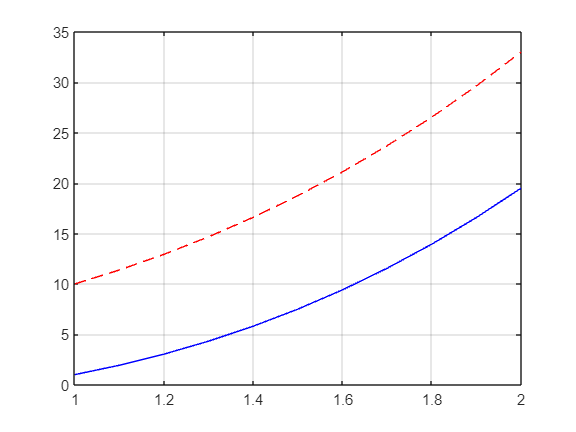

frk4 = @(x,y) y/(x+1) + 4*x^2 + 4*x;
fsol = @(x) 2*x.^3 + 2*x.^2 + 3*x + 3;
[x,y] = RK4( 0.1, frk4, 1, [1,2] );
figure;
plot( x,y, "-b", "LineWidth", 1 )
hold on
plot( x, fsol(x), "--r" );
grid on

### Ejemplo 2:


$$\frac{dy}{dx} = \frac{3}{x}y + 2x^3e^{2x}, \qquad y(1) = 0\\
D=[1,10],\quad h = 0.05$$


Solución analítica


$$y(x) = x^3(e^{2x} - e^2)$$


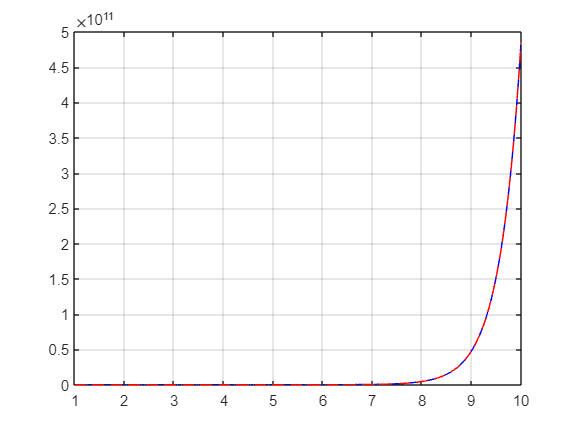

frk4 = @(x,y) 3*y/x + 2*x^3*exp(2*x);
fsol = @(x) x.^3.*(exp(2*x) - exp(2));
[x,y] = RK4( 0.05, frk4, 0, [1,10] );
figure;
plot( x,y, "-b", "LineWidth", 1 )
hold on
plot( x, fsol(x), "--r" );
grid on

### Ejemplo 3:


$$\frac{dy}{dx} = y^2\sin x, \qquad y(0) = 0.4\\
D=[0,10],\quad h = 0.05$$


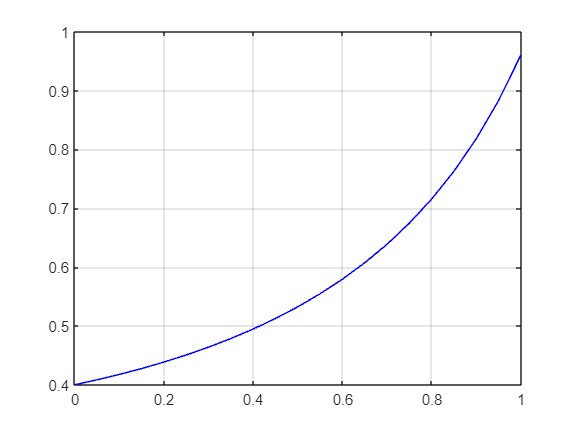

frk4 = @(x,y) y^2 * sin(x) + y^2;
[x,y] = RK4( 0.05, frk4, 0.4, [0,1] );
figure;
plot( x,y, "-b", "LineWidth", 1 )
grid on